**Print simulink**

**Nonliner cascade control**

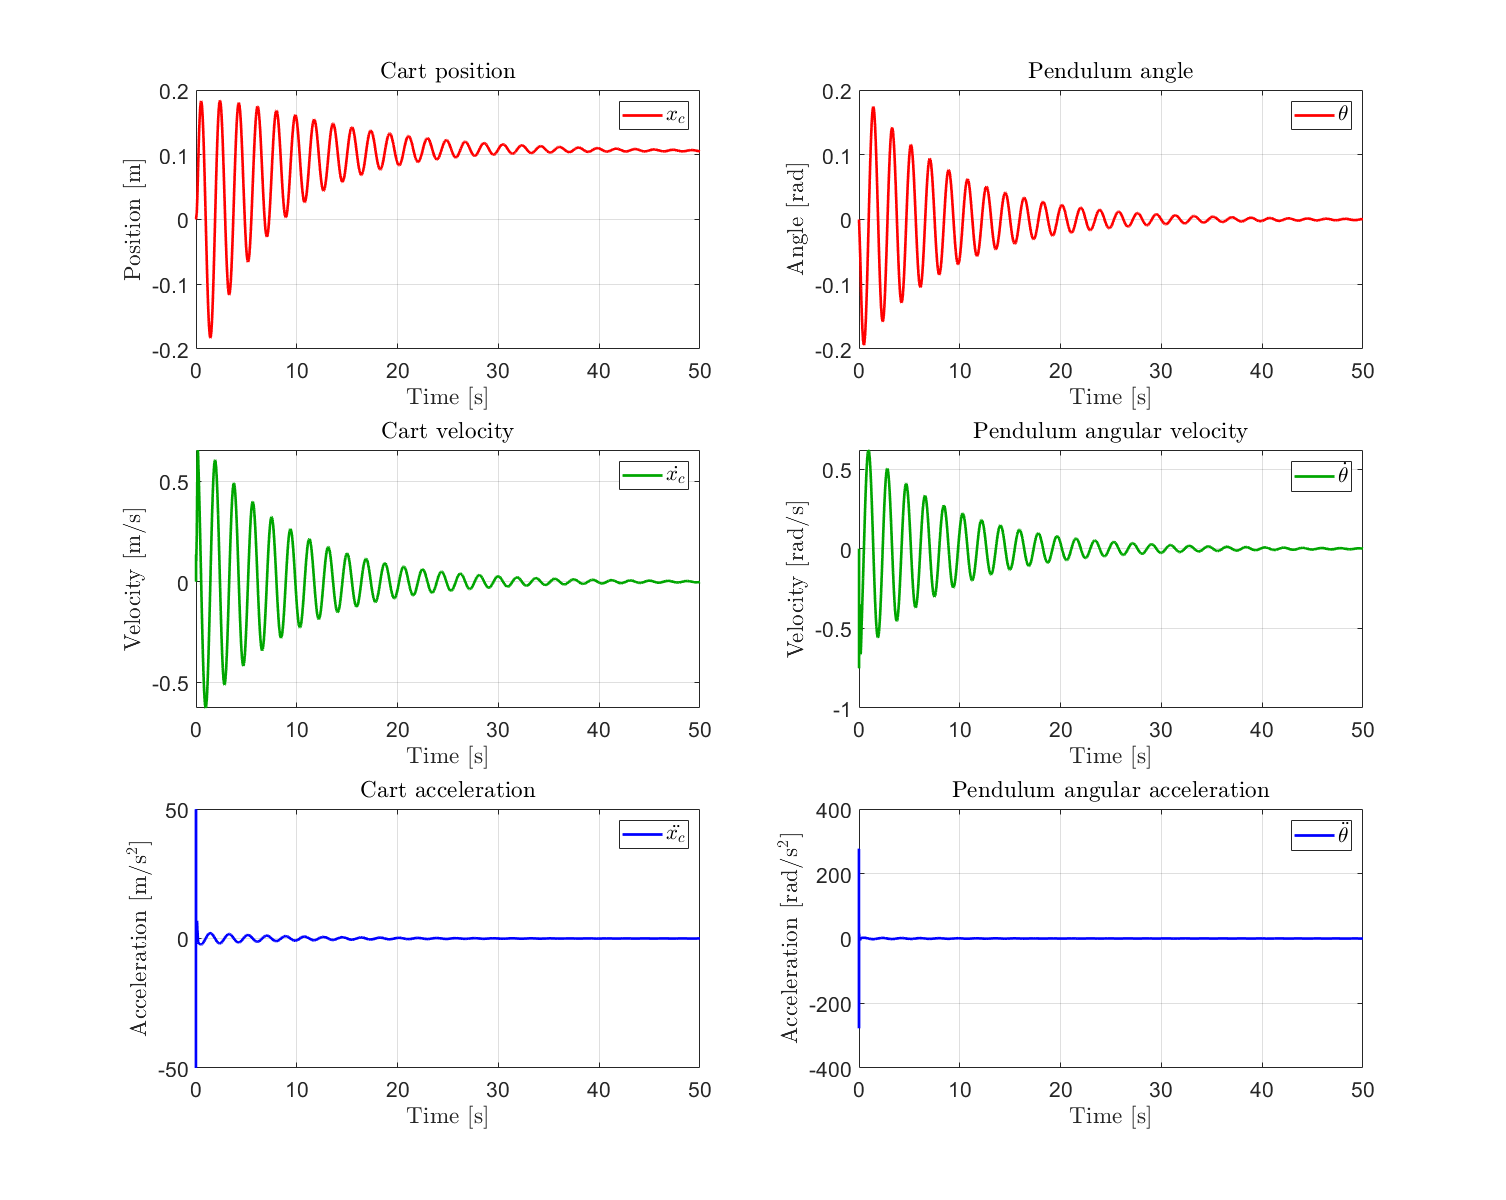

fig1 = figure('Name', 'Nonlinear cascade control','Position', [1 1 2560/1.7 1440/1.2]);

subplot(3,2,1);
plot(out.cart_pos,'r', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Position [m]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart position','Interpreter','latex','FontSize', 16)
legend('$x_c$','Interpreter','latex','FontSize', 16)

subplot(3,2,3);
plot(out.cart_vel,'Color',[0 0.65 0],'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [m/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart velocity','Interpreter','latex','FontSize', 16)
legend('$\dot{x_c}$','Interpreter','latex','FontSize', 16)

subplot(3,2,5);
plot(out.cart_acc,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [m/s$^2$]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart acceleration','Interpreter','latex','FontSize', 16)
legend('$\ddot{x_c}$','Interpreter','latex','FontSize', 16)

subplot(3,2,2);
plot(out.pend_angle, 'r', 'LineWidth',2);
title('Pendulum angle');
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Angle [rad]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angle','Interpreter','latex','FontSize', 16)
legend('$\theta$','Interpreter','latex','FontSize', 16)

subplot(3,2,4);
plot(out.pend_vel,'Color',[0 0.65 0], 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [rad/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angular velocity','Interpreter','latex','FontSize', 16)
legend('$\dot{\theta}$','Interpreter','latex','FontSize', 16)

subplot(3,2,6);
plot(out.pend_acc,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [rad/s$^2$]','Interpreter','latex', 'FontSize', 16)
title('Pendulum angular acceleration','Interpreter','latex','FontSize', 16)
set(gca,'FontSize',16)
legend('$\ddot{\theta}$','Interpreter','latex','FontSize', 16)

**Linear cascade control**

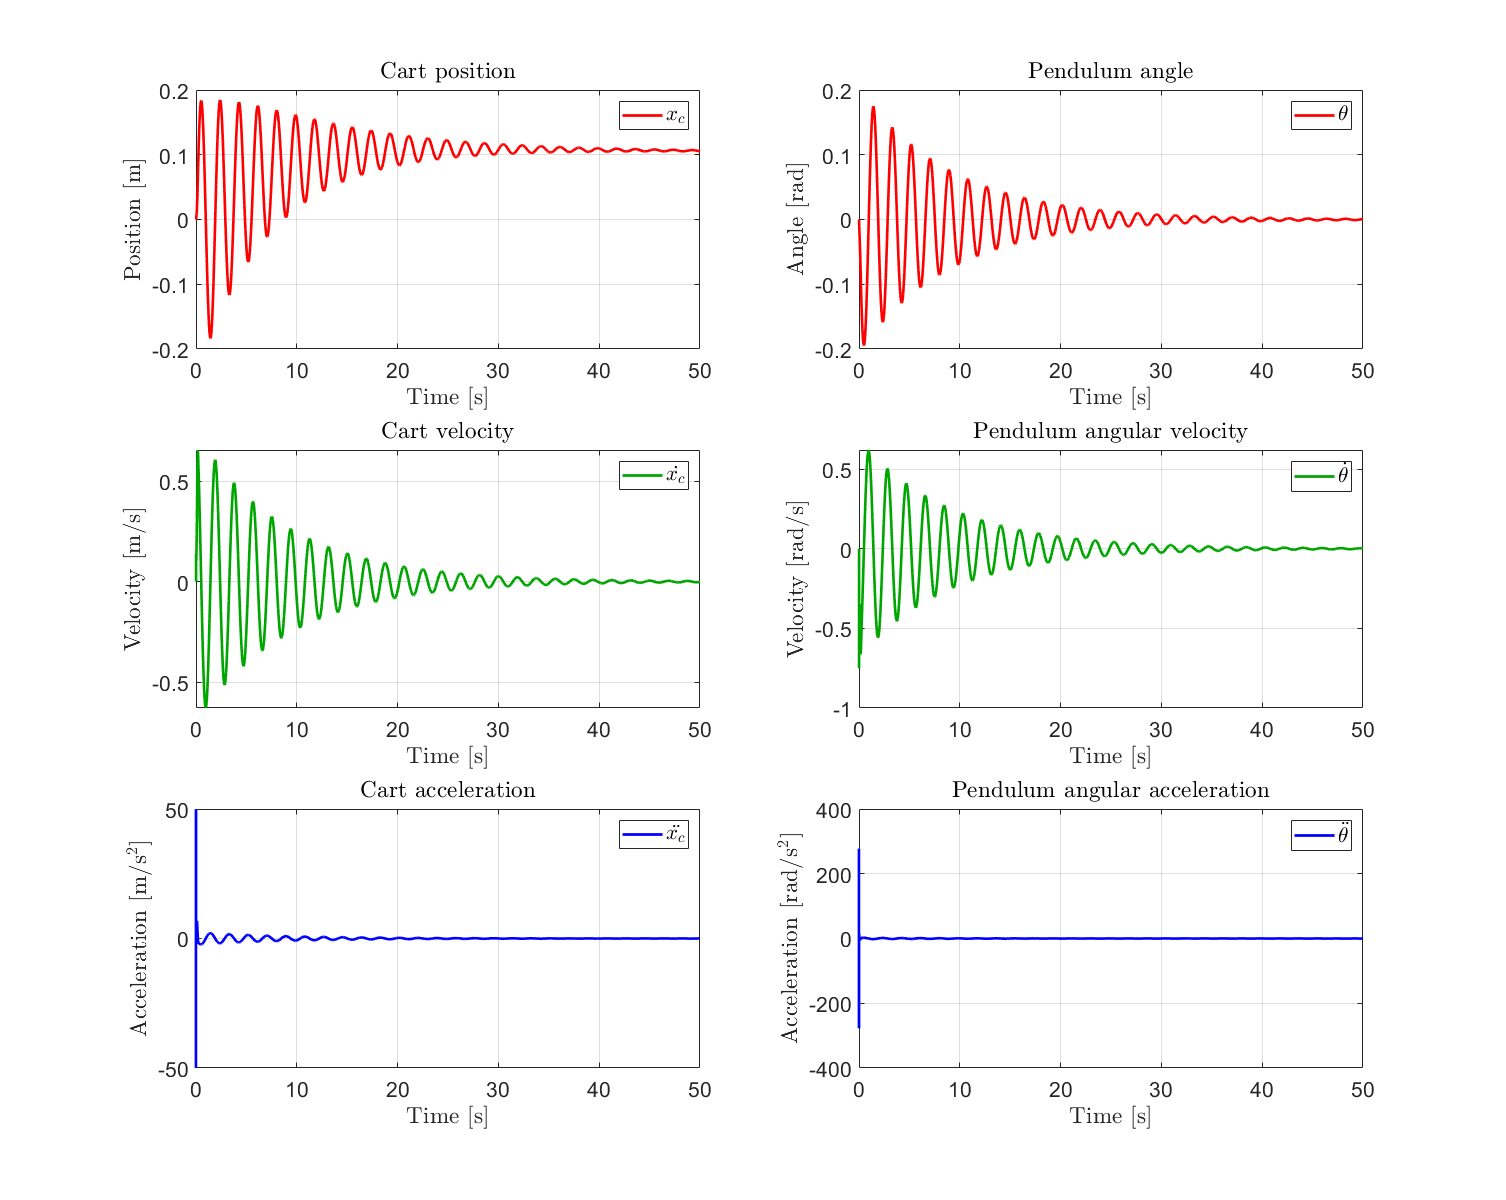

fig2 = figure('Name', 'Linear cascade control','Position', [1 1 2560/1.7 1440/1.2]);

subplot(3,2,1);
plot(out.cart_pos_lin,'r', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Position [m]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart position','Interpreter','latex','FontSize', 16)
legend('$x_c$','Interpreter','latex','FontSize', 16)

subplot(3,2,3);
plot(out.cart_vel_lin,'Color',[0 0.65 0],'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [m/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart velocity','Interpreter','latex','FontSize', 16)
legend('$\dot{x_c}$','Interpreter','latex','FontSize', 16)

subplot(3,2,5);
plot(out.cart_acc_lin,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [m/s$^2$]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart acceleration','Interpreter','latex','FontSize', 16)
legend('$\ddot{x_c}$','Interpreter','latex','FontSize', 16)

subplot(3,2,2);
plot(out.pend_angle_lin, 'r', 'LineWidth',2);
title('Pendulum angle');
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Angle [rad]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angle','Interpreter','latex','FontSize', 16)
legend('$\theta$','Interpreter','latex','FontSize', 16)

subplot(3,2,4);
plot(out.pend_vel_lin,'Color',[0 0.65 0], 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [rad/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angular velocity','Interpreter','latex','FontSize', 16)
legend('$\dot{\theta}$','Interpreter','latex','FontSize', 16)

subplot(3,2,6);
plot(out.pend_acc_lin,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [rad/s$^2$]','Interpreter','latex', 'FontSize', 16)
title('Pendulum angular acceleration','Interpreter','latex','FontSize', 16)
set(gca,'FontSize',16)
legend('$\ddot{\theta}$','Interpreter','latex','FontSize', 16)

**Integral Controller**

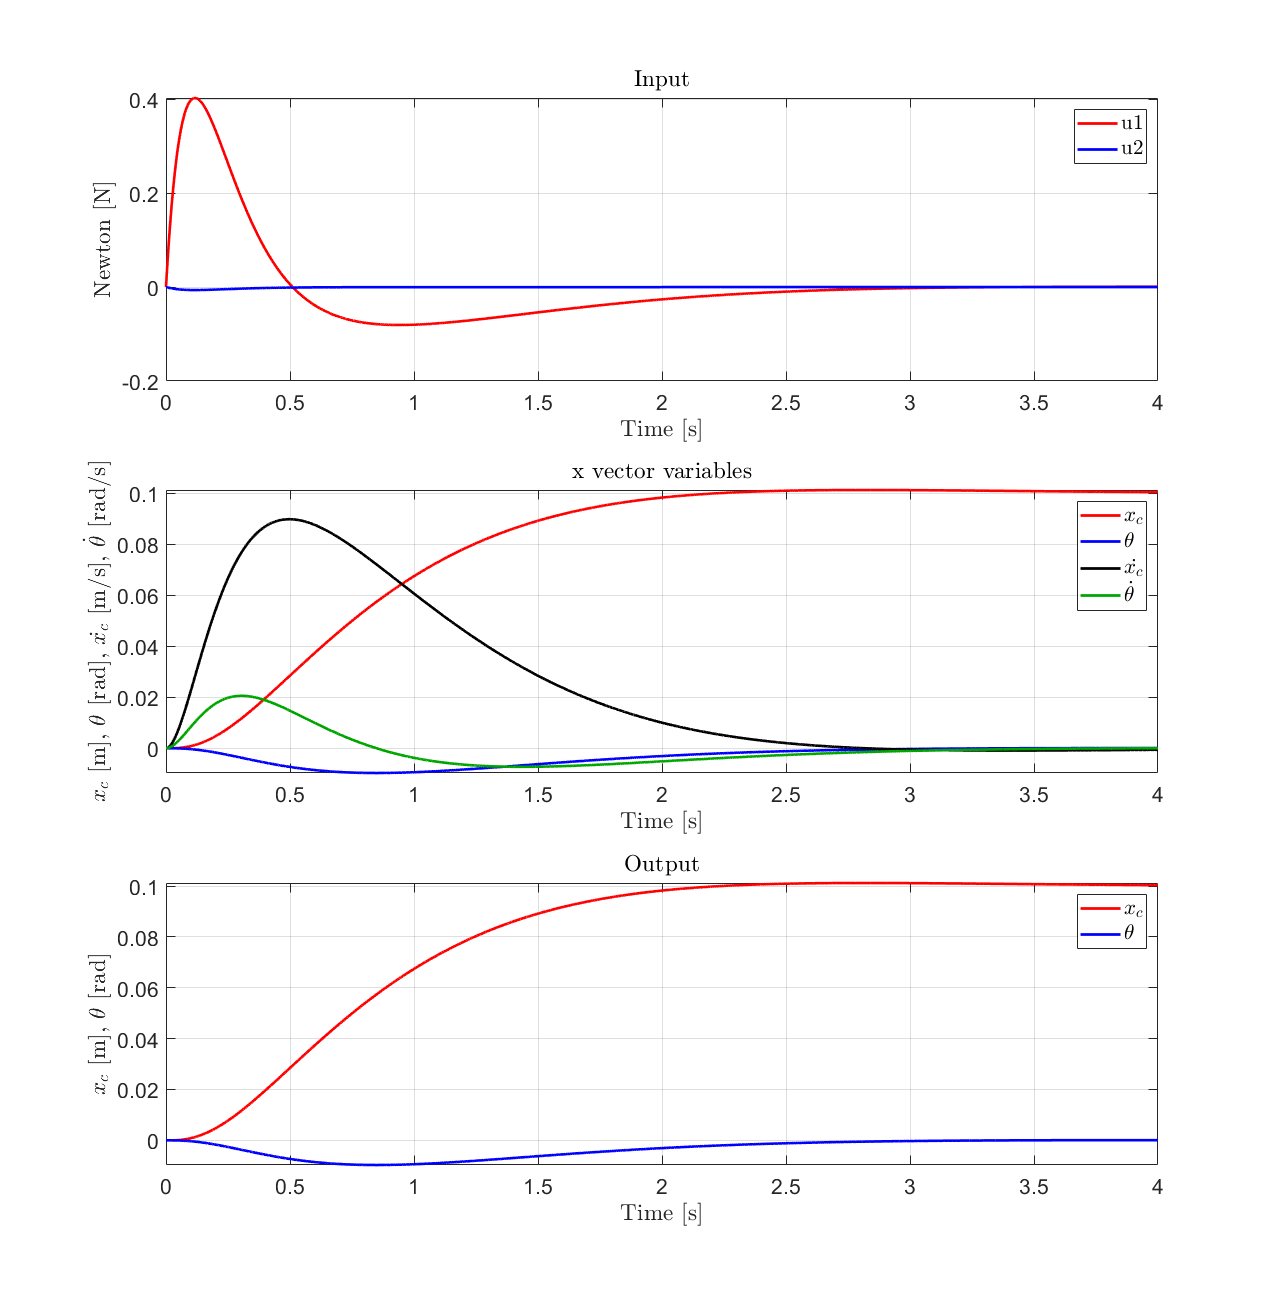

fig3 = figure('Name', 'Integral Control','Position', [1 1 2560/2 1440/1.1]);

subplot(3,1,1); 
plot(out.u1,'r', 'LineWidth',2);
hold on
plot(out.u2,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Newton [N]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Input','Interpreter','latex','FontSize', 16)
% ylim([-0.8 0.8])
legend('u1','u2','Interpreter','latex','FontSize', 16)

subplot(3,1,2);
plot(out.x,'r', 'LineWidth',2);
hold on
plot(out.th,'b','LineWidth',2);
plot(out.dx,'Color',[0 0 0],'LineWidth',2);
plot(out.dth,'Color',[0 0.65 0],'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('$x_c$ [m], $\theta$ [rad], $\dot{x_c}$ [m/s], $\dot{\theta}$ [rad/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('x vector variables','Interpreter','latex','FontSize', 16)
legend('$x_c$', '$\theta$', '$\dot{x_c}$', '$\dot{\theta}$', 'Interpreter','latex','FontSize', 16)

subplot(3,1,3);
plot(out.y2,'r', 'LineWidth',2);
hold on
plot(out.y1,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('$x_c$ [m], $\theta$ [rad]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Output','Interpreter','latex','FontSize', 16)
%ylim([-0.05 0.15])
legend('$x_c$','$\theta$','Interpreter','latex','FontSize', 16)

**Integral Controller with feedback**

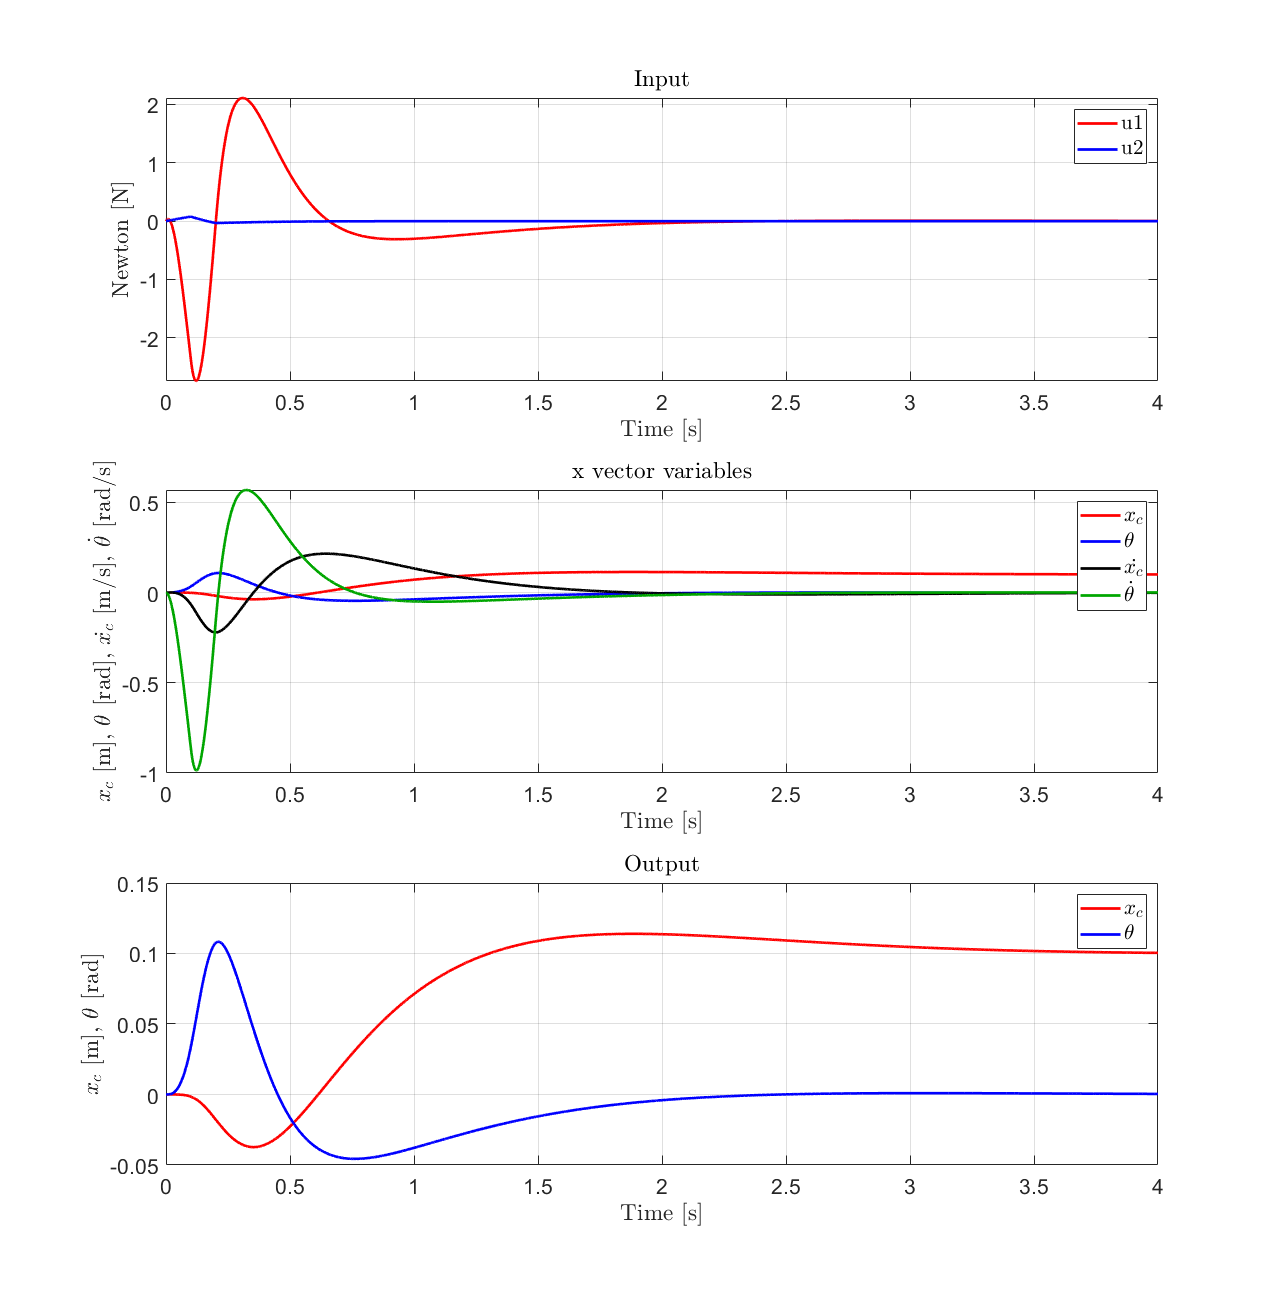

fig4 = figure('Name', 'Integral control with anti-windup','Position', [1 1 2560/2 1440/1.1]);

subplot(3,1,1);
plot(out.u1_int,'r', 'LineWidth',2);
hold on
plot(out.u2_int,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Newton [N]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Input','Interpreter','latex','FontSize', 16)
legend('u1','u2','Interpreter','latex','FontSize', 16)

subplot(3,1,2);
plot(out.x_int,'r', 'LineWidth',2);
hold on
plot(out.th_int,'b','LineWidth',2);
plot(out.dx_int,'Color',[0 0 0],'LineWidth',2);
plot(out.dth_int,'Color',[0 0.65 0],'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('$x_c$ [m], $\theta$ [rad], $\dot{x_c}$ [m/s], $\dot{\theta}$ [rad/s]','Interpreter','latex', 'FontSize', 16)
%  , '
set(gca,'FontSize',16)
title('x vector variables','Interpreter','latex','FontSize', 16)
legend('$x_c$', '$\theta$', '$\dot{x_c}$', '$\dot{\theta}$', 'Interpreter','latex','FontSize', 16)

subplot(3,1,3);
plot(out.y2_int,'r', 'LineWidth',2);
hold on
plot(out.y1_int,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('$x_c$ [m], $\theta$ [rad]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Output','Interpreter','latex','FontSize', 16)
legend('$x_c$','$\theta$','Interpreter','latex','FontSize', 16)